A = [ 10 7 8 7 ; 
      7 5 6 5 ;
      8 6 10 9 ;
      7 5 9 10 ]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


b = [ 32 23 33 31]'

b =     32
    23
    33
    31


x = A\b %"\" rezolva sistem linear

x =     1.0000
    1.0000
    1.0000
    1.0000


bp=[32.1 22.9 33.1 30.9]'

bp =    32.1000
   22.9000
   33.1000
   30.9000


xp=A\bp

xp =     9.2000
  -12.6000
    4.5000
   -1.1000


p=1

p = 1

cond(A,p) % calculeaza teoretic numarul de conditionare al matricei A

ans = 4.4880e+03

err_rel_input=errel(b,bp,p)

err_rel_input = 0.0034

err_rel_output=errel(x,xp,p)

err_rel_output = 6.8500

err_rel_output/err_rel_input

ans = 2.0379e+03

%Generăm 10 puncte echidistante în [-1, 1]
v = linspace(-1,1,10)

v =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000


V=vander(v)

V =    -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000
   -0.1042    0.1339   -0.1722    0.2214   -0.2846    0.3660   -0.4705    0.6049   -0.7778    1.0000
   -0.0050    0.0091   -0.0163    0.0294   -0.0529    0.0953   -0.1715    0.3086   -0.5556    1.0000
   -0.0001    0.0002   -0.0005    0.0014   -0.0041    0.0123   -0.0370    0.1111   -0.3333    1.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0002   -0.0014    0.0123   -0.1111    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0123    0.1111    1.0000
    0.0001    0.0002    0.0005    0.0014    0.0041    0.0123    0.0370    0.1111    0.3333    1.0000
    0.0050    0.0091    0.0163    0.0294    0.0529    0.0953    0.1715    0.3086    0.5556    1.0000
    0.1042    0.1339    0.1722    0.2214    0.2846    0.3660    0.4705    0.6049    0.7778    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0

cond(V)

ans = 4.6264e+03

Studiul condiționării pentru un polinom cu rădăcini simple

condiționarea pentru polinomul (x-1)(x-2)...(x-n), care are rădăcinile 1, 2, ..., n:

n = 20;  % Conform cerinței din problemă

% Generăm coeficienții polinomului cu rădăcinile 1, 2, ..., n
p = poly(1:n);  % În MATLAB, poly([r1, r2, ...]) returnează coeficienții polinomului cu rădăcinile r1, r2, ...

% Calculăm numărul de condiționare pentru fiecare rădăcină
for i = 1:n
    xi = i;  % Rădăcina i
    nr_cond_i = condpol(p, xi);
    fprintf('Rădăcina %d: număr de condiționare = %.4e\n', i, nr_cond_i);
end

Vizualizarea efectului perturbațiilor

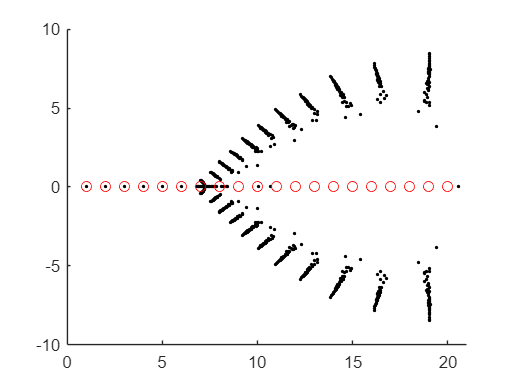

pol_test(20)

Experimentul pentru polinomul cu coeficienți a_k = 2^k

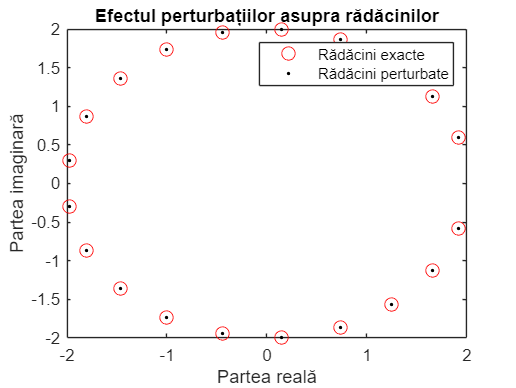

% Generăm coeficienții [1, 2, 4, 8, 16, ..., 2^n]
n = 20;
coefs = 2.^(0:n);

% Găsim rădăcinile exacte
roots_exact = roots(coefs);

% Calculăm numărul de condiționare pentru fiecare rădăcină
for i = 1:length(roots_exact)
    xi = roots_exact(i);
    if abs(imag(xi)) < 1e-10  % Doar pentru rădăcini reale
        nr_cond_i = condpol(coefs, xi);
        fprintf('Rădăcina %.4f: număr de condiționare = %.4e\n', real(xi), nr_cond_i);
    end
end

% Perturbăm coeficienții și vizualizăm efectul
perturbed_coefs = coefs + 1e-10 * randn(size(coefs));
roots_perturbed = roots(perturbed_coefs);

% Plotare
figure;
plot(real(roots_exact), imag(roots_exact), 'ro', 'MarkerSize', 8);
hold on;
plot(real(roots_perturbed), imag(roots_perturbed), 'k.', 'MarkerSize', 6);
xlabel('Partea reală');
ylabel('Partea imaginară');
title('Efectul perturbațiilor asupra rădăcinilor');
legend('Rădăcini exacte', 'Rădăcini perturbate');